# ECE 5553 Spring 2020 Project/Homework 5 

Please modify the code below  for each task. 

# Example Code from MATLAB : Plan Mobile Robot Paths using RRT

This example shows how to use the rapidly-exploring random tree (RRT) algorithm to plan a path for a vehicle through a known map. Special vehicle constraints are also applied with a custom state space. You can tune your own planner with custom state space and path validation objects for any navigation application.

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

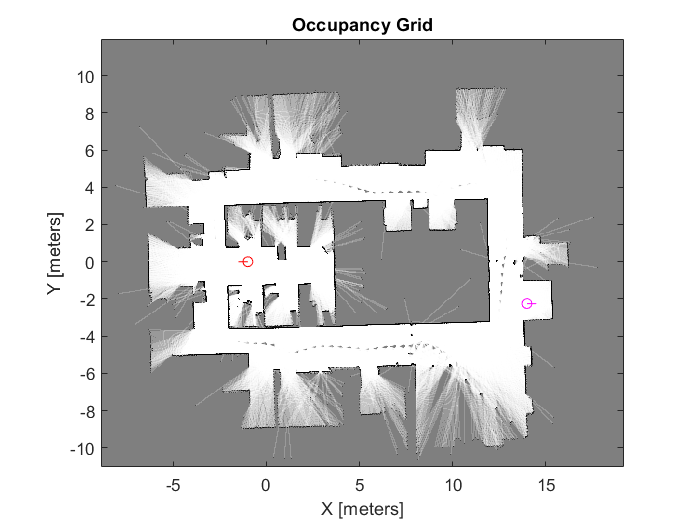

load("office_area_gridmap.mat", "occGrid")
show(occGrid)

% Set the start and goal poses
start = [-1.0, 0.0, -pi];
goal = [14, -2.25, 0];

% Show the start and goal positions of the robot
hold on
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')

% Show the start and goal headings
r = 0.5;
plot([start(1), start(1) + r*cos(start(3))], [start(2), start(2) + r*sin(start(3))], 'r-' )
plot([goal(1), goal(1) + r*cos(goal(3))], [goal(2), goal(2) + r*sin(goal(3))], 'm-' )
hold off

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4m allows for tight turns in this small environment.

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05m. This distance discretizes the path connections and checks obstacles in the map based on this.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss, stateValidator);
planner.MaxConnectionDistance = 2;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Because of the random sampling, this example sets the `rng` seed for consistent results.

rng(0,'twister')

[pthObj, solnInfo] = plan(planner, start, goal);

## Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

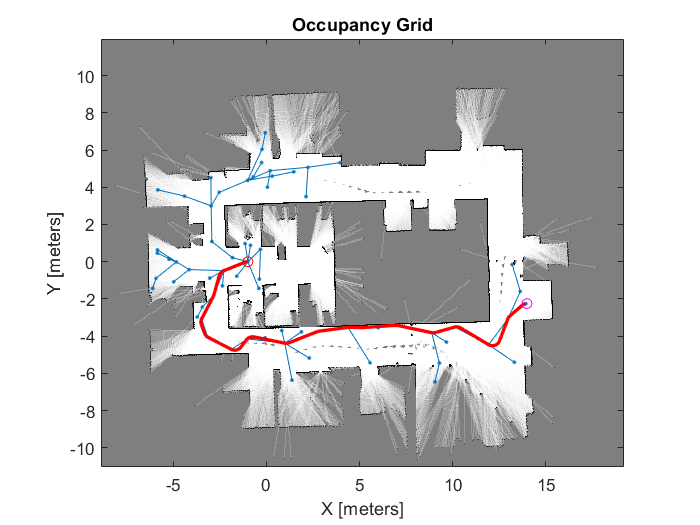

show(occGrid)
hold on

% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');

% Interpolate and plot path
interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)

% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off